# Initialization

This is to compute MC on the real robot with a 3 mm blade leg, both actuated Key difference is that the bin size is 100

clear;

% Load data
load("C:\Users\vjc28\OneDrive\Documents\dissertation\robot_properties_solo-master\Models\flipper\crawling_data.mat");
% Name our dataset
myStruct.name = 'Flipper_data_sand';

## 1. Step: Extract min/max values for each column that will be used

Define initial min/max values

position_X_min  = 0; 
position_X_max = 289.13;
load_min = 0; 
load_max = 256;

% Initialize string for output
real_string = '';

% Assuming myStruct is populated with data from crawling_data.mat
% Uncomment the next lines to load data into myStruct if needed
% myStruct.motor2_position_X  = position_X_crawl(:,31); % Joint angle of hip
% myStruct.motor2_load        = load_crawl(:,31); % Load data

% Get the max/min values of position data
position_X_min = min(myStruct.motor2_position_X);
position_X_max = max(myStruct.motor2_position_X);

% Get the max/min values of load data
load_min = min(myStruct.motor2_load);
load_max = max(myStruct.motor2_load);

real_string = [real_string 'Domains\n' ...
    sprintf('  Position:        %f, %f\n', position_X_min, position_X_max) ...
    sprintf('  Load:        %f, %f\n', load_min, load_max)];

## Discretise Test

bins = 31;  % Number of bins for discretization
fprintf('Bins = %d\n', bins)
%cd 'C:\Users\vjc28\OneDrive\Documents\dissertation\robot_properties_solo-master\Models'
% Call the discretiseMatrix function for position and load
myStruct.discrete_position = discretiseMatrix(myStruct.motor2_position_X, position_X_min, position_X_max, bins);

myStruct.discrete_load = discretiseMatrix(myStruct.motor2_load, load_min, load_max, bins);

## Visualize bins:

fprintf('Discrete Position:\n');

Discrete Position:


disp(myStruct.discrete_position);

    1
    1
    1
    1
    2
   11
   11
   12
   16
   19
   22
   26
   30
   31
   31
   31
   31
   31
   31
   31
   31
   31
   28
   24
   20
   16
   12
    8
    4
    1
    1




fprintf('Discrete Load:\n');

Discrete Load:


disp(myStruct.discrete_load);

    1
    1
    1
    1
    6
    1
    1
    8
   12
   21
   29
   22
   29
   31
   27
   11
    8
    1
    8
    1
    1
    1
    4
    4
    8
    8
    9
    8
    7
    7
    1



## run MC quantification

fprintf('Working on file %s\n', myStruct.name)

Working on file Flipper_data_sand



myStruct.w2= myStruct.discrete_position(2:end,:);
myStruct.w1 = myStruct.discrete_position(1:end-1,:);

myStruct.a1 = myStruct.discrete_load(1:end-1,:);

%Total MC
myStruct.mcw  = MC_W1(myStruct.w2, myStruct.w1, myStruct.a1);
fprintf('MC_W %f\n', myStruct.mcw);

MC_W 1.024300


%Dynamic MC
myStruct.mcd  = MC_W1_dynamic(myStruct.w2, myStruct.w1, myStruct.a1);
mean(myStruct.mcd)

ans = 1.0243

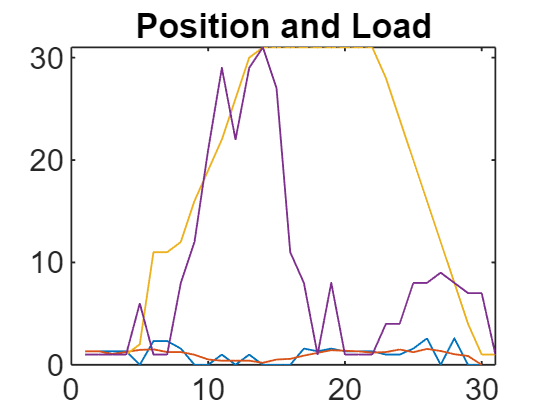

%plotting

plot(myStruct.discrete_position)
title ('Position and Load')
hold on;
plot(myStruct.discrete_load);
hold off;

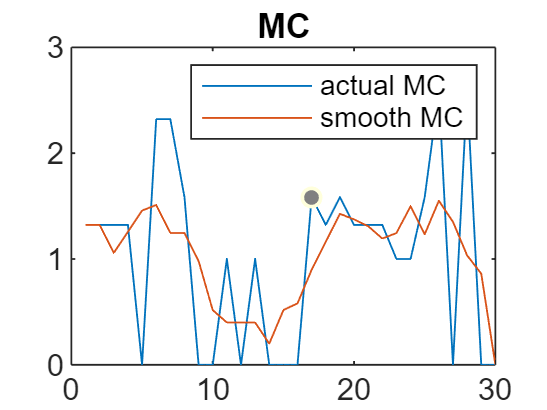

plot(myStruct.mcd)
hold on;
plot (smooth(myStruct.mcd))
legend('actual MC', 'smooth MC')
title ('MC');